## Controlador Proporcional Integral Deriviativo

(Siendo Gp = 1/((s+0.5)(s+1)))

[num, den] = zp2tf([''], [-1 -0.5], 1);
Gp = tf(num, den)


Gp =
 
          1
  -----------------
  s^2 + 1.5 s + 0.5
 
Continuous-time transfer function.
Model Properties


Kp=1;
Ti=1;
Td=0.5;
num=[Kp*Ti*Td Kp*Ti Kp];
den=[Ti 0];
Gc=tf(num, den)


Gc =
 
  0.5 s^2 + s + 1
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


H=1;

FTLA=Gc*Gp*H


FTLA =
 
     0.5 s^2 + s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


FTTD=Gc*Gp


FTTD =
 
     0.5 s^2 + s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


FTLC=feedback(FTTD, H)


FTLC =
 
      0.5 s^2 + s + 1
  -----------------------
  s^3 + 2 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties


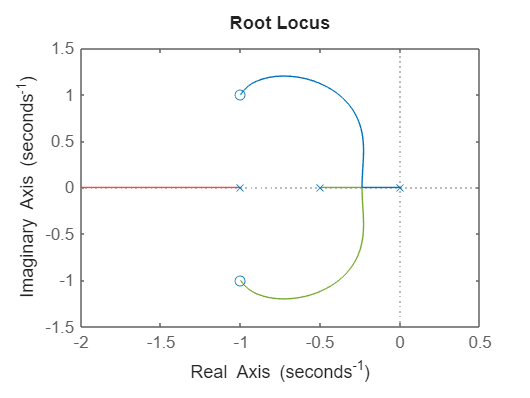


rlocus(FTLA)
xlim([-2 0.5])
ylim([-1.5 1.5])

Salidas del sistema en Lazo Cerrado

Kp=1;
Ti=1;
Td=0.1;
num=[Kp*Ti*Td Kp*Ti Kp];
den=[Ti 0];
Gc=tf(num, den)


Gc =
 
  0.1 s^2 + s + 1
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


FTTD=Gc*Gp


FTTD =
 
     0.1 s^2 + s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


FTLC1=feedback(FTTD, H)


FTLC1 =
 
       0.1 s^2 + s + 1
  -------------------------
  s^3 + 1.6 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties



Kp=1;
Ti=1;
Td=2;
num=[Kp*Ti*Td Kp*Ti Kp];
den=[Ti 0];
Gc=tf(num, den)


Gc =
 
  2 s^2 + s + 1
  -------------
        s
 
Continuous-time transfer function.
Model Properties


FTTD=Gc*Gp


FTTD =
 
      2 s^2 + s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


FTLC2=feedback(FTTD, H)


FTLC2 =
 
        2 s^2 + s + 1
  -------------------------
  s^3 + 3.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties



Kp=1;
Ti=1;
Td=10;
num=[Kp*Ti*Td Kp*Ti Kp];
den=[Ti 0];
Gc=tf(num, den)


Gc =
 
  10 s^2 + s + 1
  --------------
        s
 
Continuous-time transfer function.
Model Properties


FTTD=Gc*Gp


FTTD =
 
     10 s^2 + s + 1
  ---------------------
  s^3 + 1.5 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


FTLC3=feedback(FTTD, H)


FTLC3 =
 
        10 s^2 + s + 1
  --------------------------
  s^3 + 11.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties



figure(1)
step(FTLC1, 'r', FTLC2, 'b', FTLC3, 'g')
hold on
t=(-1:0.01:20)

t =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


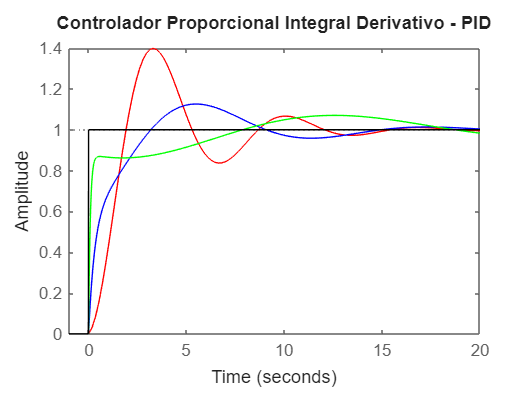

unitstep= t>=0;
plot(t, unitstep, 'k')
title('Controlador Proporcional Integral Derivativo - PID')
xlim([-1 20])